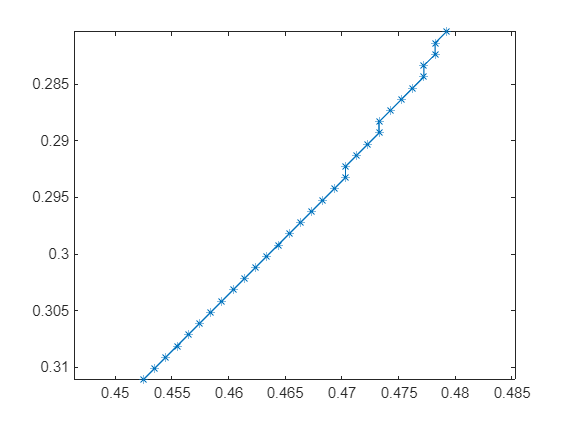

% Load data
load MathWorksLogo.mat segmentsPix xLimPix yLimPix
nSegments = length(segmentsPix);
load WhiteboardLimits.mat xLim yLim
fraction = 0.7;
segmentsMeters = transformPixelsToMeters(segmentsPix,xLim,yLim,xLimPix,yLimPix,fraction);

% Plot
MiSu = segmentsMeters{2};
plot(MiSu(:,1),MiSu(:,2),'-*')
axis equal ij



radius = 0.002; %Max distance between points to draw (meters)
% Alvin = reduceSegment(MiSu,radius);


% function reducedSegment = reduceSegment(MiSu,radius)
nPoints = size(MiSu,1); %% 32
keepPoint = true(nPoints,1); %% logical true for 32 point
reference = 1; %% the starting point
test = 2; %% the next point from 


reference
test

MiSu(test,:)                           %% [0.4782	0.2814]
MiSu(reference,:)                      %% [0.4792	0.2804]
MiSu(test,:) - MiSu(reference,:)       %% [-0.009899 0.009899]

norm(MiSu(test,:) - MiSu(reference,:)) %% 0.0014

if norm(MiSu(test,:) - MiSu(reference,:)) < radius
    keepPoint(test) = false;
    test = test + 1;
else
    reference = test;
    test = reference + 1;
end

reference
test







MiSu(test,:)                           %% [0.4782	0.2814]
MiSu(reference,:)                      %% [0.4792	0.2804]
MiSu(test,:) - MiSu(reference,:)       %% [-0.009899 0.009899]

norm(MiSu(test,:) - MiSu(reference,:)) %% 0.0014

% confirm it with equation of pythagorean theorem

if norm(MiSu(test,:) - MiSu(reference,:)) < radius
    keepPoint(test) = false;
    test = test + 1;
else
    reference = test;
    test = reference + 1;
end



while test < nPoints  %% 2 < 32
    if norm(MiSu(test,:) - MiSu(reference,:)) < radius
        keepPoint(test) = false;
        test = test + 1;
    else
        reference = test;
        test = reference + 1;
    end
end
Alvin = MiSu(keepPoint,:);

% Loop through the segment and decide which points to remove. 
% By default, keep all point
% Select points to keep and remove such that each consecutive point remaining is separated by a
% minimum distance from the previous point

while test < nPoints  %% 2 < 32
    % norm() 
    % Check if distance(reference point and test point) < r. 
    % If it is, mark the test point for removal and test the next point in the segment.
    if norm(MiSu(test,:) - MiSu(reference,:)) < radius
        % If so, mark test point for removal and test the next point
        keepPoint(test) = false;
        test = test + 1;

    % If the distance > r, make the test point the new reference point
    %  begin testing the next point in the segment.
    else
        % If not, update reference and test points
        reference = test;
        test = reference + 1;
    end
end

Alvin = MiSu(keepPoint,:);

keepPoint

%Plot
for ii = 1:nSegments
    xy = segmentsMeters{2};
    plot(xy(:,1),xy(:,2),'-*')
    hold on
end
hold off
axis equal ij
title('Paths to draw (meters)')